clear

addpath("functions\")

#### Add defect to plate

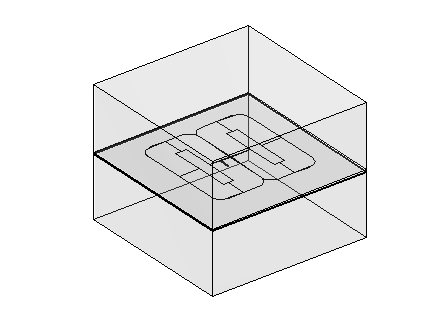

Model = myModel;
freqs = [1000 2000 4000 16000]; % (Hz)
mesh_size = 4; % 1:finest 9:coarsest

Model = ComsolInterface('Build', Model);

% ComsolInterface('AddCircularDefect', Model, -0.004, -0.008, 0.003,    0.0e-3, -1.0e-3)
% ComsolInterface('AddCircularDefect', Model,  0.008, -0.004, 0.003,   -0.5e-3, -1.5e-3)
% ComsolInterface('AddCircularDefect', Model,  0.004,  0.008, 0.003,   -1.0e-3, -2.0e-3)
% ComsolInterface('AddCircularDefect', Model, -0.008,  0.004, 0.003,    0.0e-3, -0.5e-3)
% ComsolInterface('AddCircularDefect', Model, -0.008,  0.004, 0.003,   -1.5e-3, -2.0e-3)

ComsolInterface('AddRectangularDefect', Model, -5.75e-3,0, 0.5e-3, 9e-3,  0.0e-3,-0.5e-3)
ComsolInterface('AddRectangularDefect', Model,  5.75e-3,0, 0.5e-3, 9e-3, -1.0e-3,-1.5e-3)

figure
ComsolInterface('PlotGeometry', Model)

#### Compute fields

x_s = Model.sensors.positions(1,:);
y_s = Model.sensors.positions(2,:);
z_s = Model.sensors.positions(3,:);

delta_B = zeros(size(Model.sensors.positions,2), 1, length(freqs));
for i = 1:length(freqs)
    tic
    ComsolInterface('Solve', Model, freqs(i), mesh_size, true);
    [Bx, By, Bz] = ComsolInterface('EvaluateField', Model, {'Bx' 'By' 'Bz'}, x_s,y_s,z_s);
    B1 = dot([Bx;By;Bz], Model.sensors.axes);
    fprintf("Solve %g Hz with defects took %.2f seconds\n", freqs(i), toc)

    tic
    ComsolInterface('Solve', Model, freqs(i), mesh_size, false);
    [Bx, By, Bz] = ComsolInterface('EvaluateField', Model, {'Bx' 'By' 'Bz'}, x_s,y_s,z_s);
    B2 = dot([Bx;By;Bz], Model.sensors.axes);
    fprintf("Solve %g Hz without defects took %.2f seconds\n", freqs(i), toc)

    delta_B(:,:,i) = B1 - B2;
end

Solve 1000 Hz with defects took 381.55 seconds


Solve 1000 Hz without defects took 352.21 seconds


Solve 2000 Hz with defects took 416.77 seconds


Solve 2000 Hz without defects took 404.90 seconds


Solve 4000 Hz with defects took 403.95 seconds


Solve 4000 Hz without defects took 362.81 seconds


Solve 16000 Hz with defects took 345.73 seconds


Solve 16000 Hz without defects took 345.20 seconds



clear x_s y_s z_s i B1 B2

#### Export sensor data

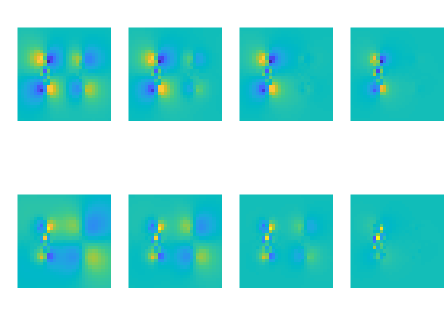

filename = sprintf('data/delta-B_%s.txt', datetime('now','Format','MMdd-HHmm'));
global defects
LoadSaveData(filename, delta_B, freqs, defects)

plot_sensor_data(filename)